%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader toehold length on DNA/RNA TMSD kinetics including
%spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

%g = 2 %define invader toehold length

R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

%dGrd = -0.2*R*temp
dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant 
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(5,15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(5, 15)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(5, 15)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through dGrd values 
for dG = 0:-0.1:-0.4
    dGrd = dG*R*temp
    %loop through invader toehold lengths 
    for g = 1:15

        %define forward and reverse transition rates
        k_AA = 0;
        k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
        k_B1A = k_bp * exp(dGbp/(R*temp))
        k_BC1ij = k_bp;
        k_BC1ji = k_bp * exp(dGbp/(R*temp));
        k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
        k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))
        k_Cr = k_bp * exp(-dGbm/(R*temp));
        k_CD = k_bp * exp(-(dGbm - dGrd)/(R*temp));
        k_DC = 0 
        k_DD = 1
    
        if g == 1
            %create arrays of forward and reverse transition rates
            Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, k_AB1]
            Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_B1A, k_AA]
        
            %define spontaneous incumbent dissociation rates
            Koff = [0];
            for n = 1:b-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
            end
            Koff = horzcat(Koff, [0, 0])
        
        else
            %create arrays of forward and reverse transition rates
            Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
            %define spontaneous incumbent dissociation rates
            Koff = [0]; 
            for n = 1:b-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
            end
            Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        end
    
        Pn_jN_1 = zeros(1,numel(Kf))
        jn_jN_1 = zeros(1,numel(Kf))
        Pn_jN_1 (1) = 0;
        jn_jN_1 (1) = 1;
        
        %calculate flux between each state
        for Pn = 2:numel(Kf)
            Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
            jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
        end
        
        first_pass_time (round(-10*dG+1), g) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %calculate first passage time
        k_eff (round(-10*dG+1), g) = 1/(first_pass_time (round(-10*dG+1), g)*(5*10^-8)); %calculate effective rate constant
        prob_unbound(round(-10*dG+1), g) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate prob of being in unbound state
    end
end

dGrd = 0

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+04 *

    0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022    0.0002         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022    0.0002    0.0001         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGrd = -0.0592

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    2.9867    0.0816    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448         0


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 816.0655

k_Cf = 2.9867e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.9314    0.2862    0.0208    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGrd = -0.1185

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    2.7024    0.0738    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000    0.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.5572    0.2343    0.0154    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.4174    0.0336    0.0027    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.1988    0.0965    0.0078    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    4.3396    0.3492    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGrd = -0.1777

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    2.4453    0.0668    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448         0


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    3.2187    0.1919    0.0114    0.0007    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGrd = -0.2370

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    2.2126    0.0605    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448         0


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000    0.0000         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849    0.8630         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849    0.8630    0.6104         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849    0.8630    0.6104    0.5426         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849    0.8630    0.6104    0.5426    0.5361         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849    0.8630    0.6104    0.5426    0.5361    0.5356         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849    0.8630    0.6104    0.5426    0.5361    0.5356    0.5356         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849    0.8630    0.6104    0.5426    0.5361    0.5356    0.5356    0.5356         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849    0.8630    0.6104    0.5426    0.5361    0.5356    0.5356    0.5356    0.5356         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 604.5562

k_Cf = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    2.9124    0.1571    0.0085    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     0.0417    0.0034    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1199    0.0096    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.4340    0.0349    0.0028    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.8603    0.1497    0.0120    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.9168    0.7174    0.0577    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9999    0.9988    0.9928    0.9881    0.9875    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874    0.9874
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9882    0.9650    0.9584    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577    0.9577
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9856    0.9129    0.8537    0.8453    0.8445    0.8445    0.8445    0.8445    0.8445    0.8445
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9849    0.8630    0.6104    0.5426    0.5361    0.5356    0.5356    0.5356    0.5356    0.5356


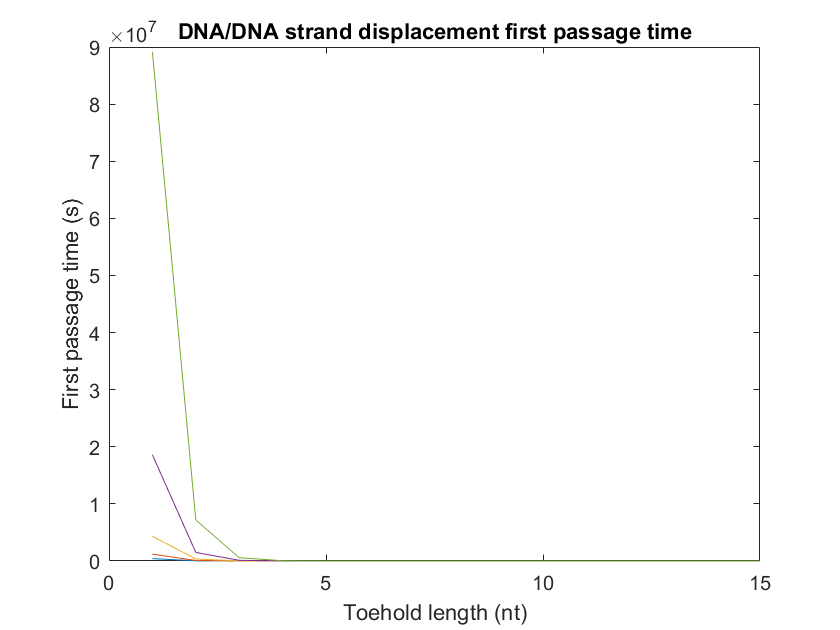

plot(1:15, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

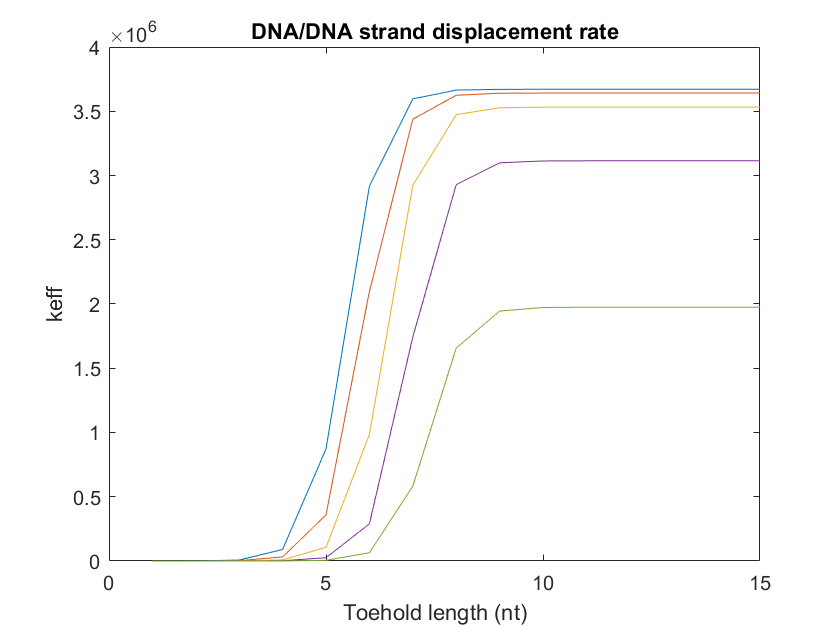


plot(1:15, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')


ax = gca;
%dark_blue = 1/255*[31,120,180];
%medium_blue = 1/255*[95, 141, 211]
%light_blue  = 1/255*[146,197,222];
%rred = 1/255*[202,0,32];
%maroon = 1/255*[170, 0, 0]
%teal = 1/255*[55, 200, 171]
%purple = [0.4940, 0.1840, 0.5560]
%indigo = 1/255*[198, 175, 233]
%colour = [[rred]; [purple]; [indigo]; [dark_blue]; [light_blue]]

blue_1 = 1/255*[22, 45, 82];
blue_2 = 1/255*[38, 68, 156];
blue_3 = 1/255*[44, 125, 205];
blue_5 = 1/255*[162, 220, 239];
blue_4 = 1/255*[110, 186, 239];
blue_6 = 1/255*[190, 215, 225];
colour = [[blue_1]; [blue_2]; [blue_3]; [blue_4]; [blue_5]];

for dG = 1:5
    plot(1:15, log10(k_eff(dG, :)), 'Color', colour(dG, :), 'linewidth', 2)
    hold on
    scatter(1:15, log10(k_eff(dG, :)),[], colour(dG, :),  'filled', 'HandleVisibility', 'off')
end
legend('DNA', '-0.1RT','-0.2RT', '-0.3RT', '-0.4RT', 'location', 'southeast')
ax.LineWidth = 1.5

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [-1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [-1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [-1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


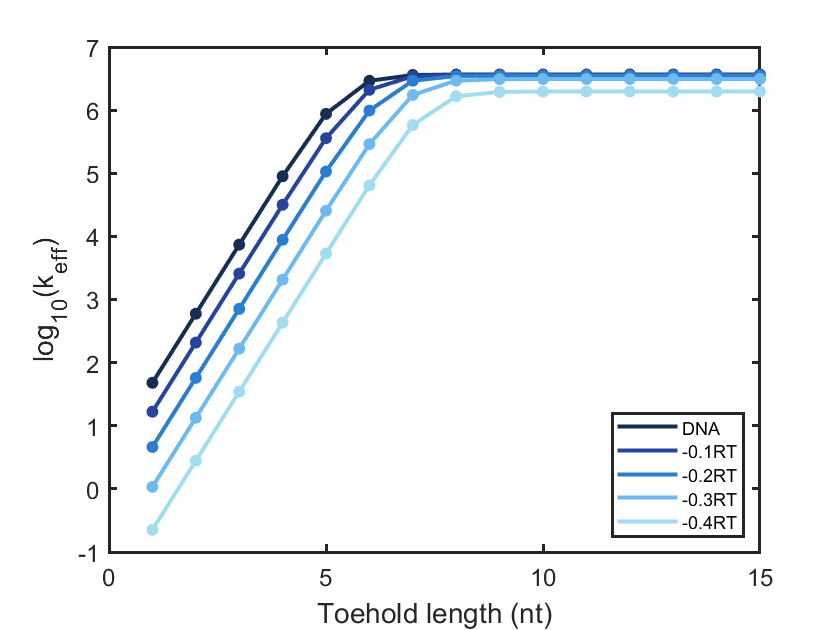

xlabel('Toehold length (nt)', 'FontSize', 14)
ylabel('log_1_0(k_e_f_f)', 'FontSize', 14)
hold off